# Solver Profiler

Copyright 2023-2024 The MathWorks, Inc.

The Solver Profiler can be used to examine the solver behaviour and identify issues that contribute to poor simulation performance. The Solver Profiler reports on different events that can contribute to major events that occur when simulating a model:

- Zero-crossing events

- Solver exception events

- Solver reset events

- Jacobian computation events

Open a model:

openExample('simscapeelectrical/SinglePhaseGridSolarPVExample')  

Open the Solver Profiler:

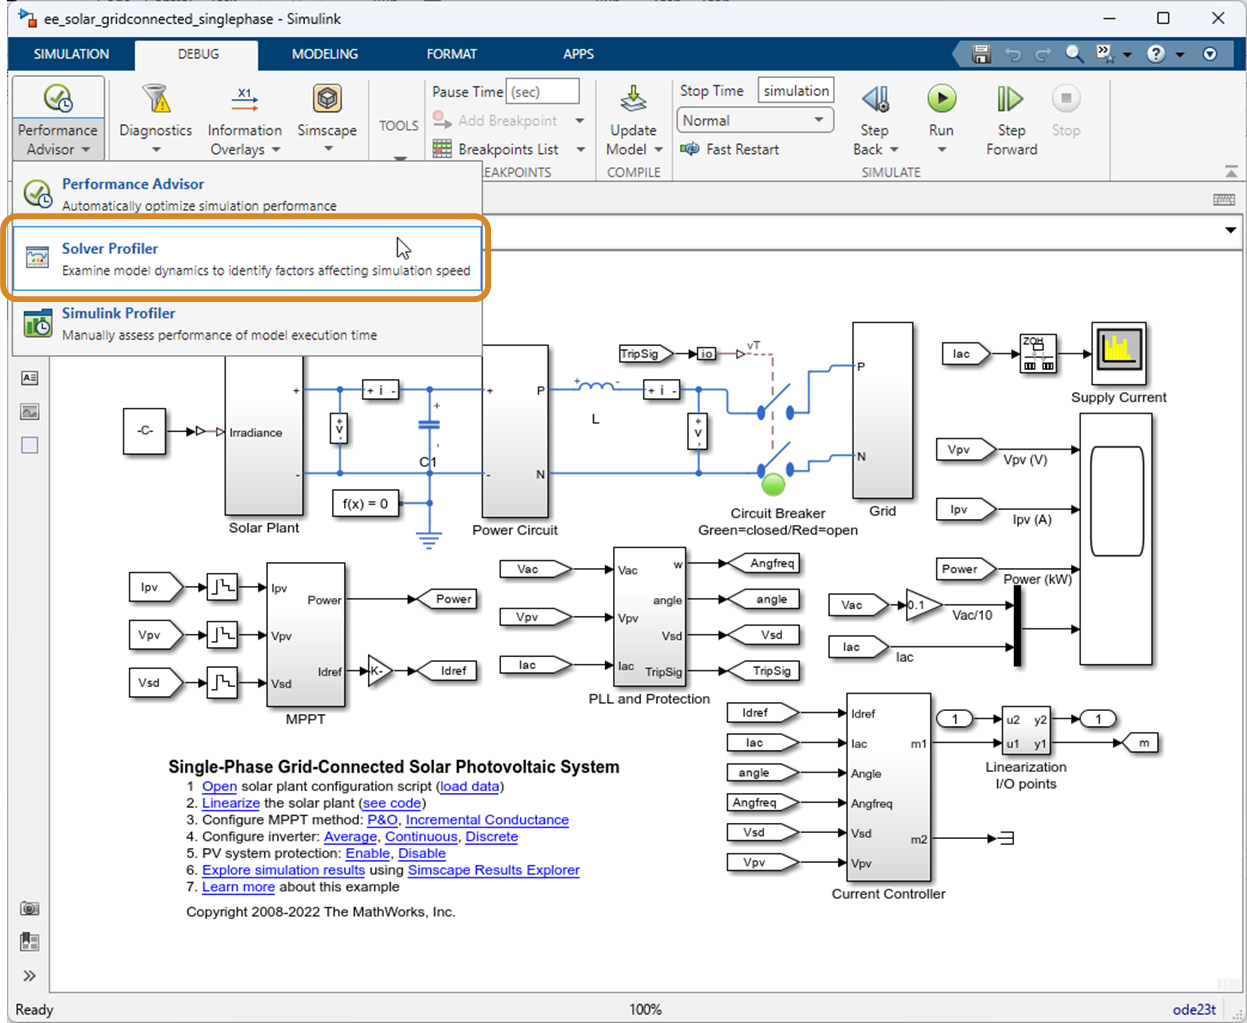

Run Simulation from the Solver Profiler and collect statistics, enabling *Continuous States*, *Simscape States* and *Zero Crossings* allows to access additional exploring options after the simulation:

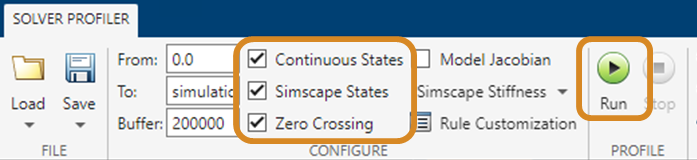

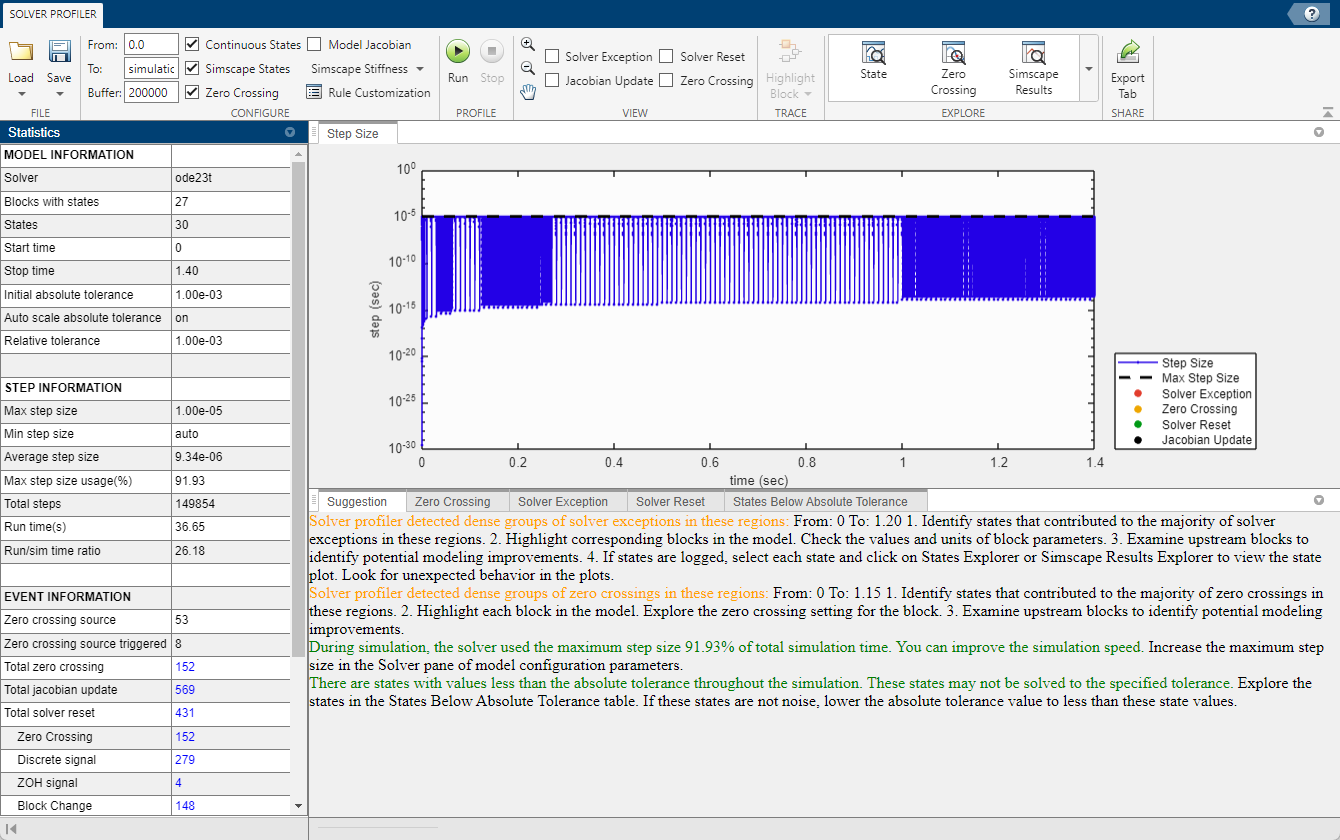

The report gives an overview on general solver statistics. The graph shows how the step size varies throughout the simulation. Possible bottlenecks that are typically shown are:

- Solver Exceptions: Scale tolerances appropriately for system

- Small step size at start of simulation: Starting from an operating point helps eliminate transient behaviour

- Zero Crossings: Investigate frequency and cause of zero-crossings in your model

The pane below the graph allows to dig deeper into the different events. From there you can see which states and blocks contribute the most. The different tabs show:

- Suggestions: Some general hints the Solver Profiler makes based on the captured data. Points to possible improvements or suggests where to investigate further. 

- Zero Crossing: Lists sources of zero crossing events. (About [Zero Crossing Detection](https://www.mathworks.com/help/releases/R2022b/simulink/ug/zero-crossing-detection.html))

- Solver Exception: Summarizes which blocks and states trigger the exceptions and which kind of exception it is. (About [Solver Exception Events](https://www.mathworks.com/help/releases/R2022b/simulink/ug/solver-exception-events.html))

- Solver Reset: Logs those events hat cause the solver to reset. it also breaks down onto the types of rest events. (About [Solver Resets](https://www.mathworks.com/help/releases/R2022b/simulink/ug/solver-resets.html)) 

 To investigate further and assess if they capture important system dynamics or add unwanted "noise" you can also use additional viewers:

- State Explorer: View dynamics of continuous states in the model. Use this to explore statistics like state and derivative value and error control for individual states. To use this make sure *Continuous States* is enabled. 

- Zero Crossing Explorer: Visualizes zero crossing detectio behaviour for the simulation. Use this to investigate zero crossings events in more detail. To use this make sure that *Zero Crossing* is enables. 

- Simscape Results: Allows to navigate directly to the Simscape Results Explorer for Simscape states in the system. Make sure that *Simscape States* is enabled to use this. 